load LinearTrackRF_analisys.mat

org = Org; org.init;

mus = org.fetch('mus');
mus = mus{69};

mus = cell2mat(mus)

mus =     1.9255    1.3982    1.2724    1.3405    1.3906    1.3993    1.4219    1.4361    1.4115    1.3448    1.2412    1.1179    0.9867    0.8685    0.7586    0.6289    0.4960    0.3616    0.3070    0.5360    0.1487    0.0419    0.0640    0.0873    0.1146    0.1365    0.1707    0.2132    0.2563    0.2888    0.3396    0.4027    0.4650    0.5555    0.6485    0.7288    0.7740    0.6834    0.5365    0.5505
    1.2157    0.9996    0.9050    1.0666    1.1814    1.2300    1.2274    1.1968    1.1445    1.0682    0.9734    0.8719    0.7647    0.6546    0.5447    0.4419    0.3472    0.2547    0.1754    0.7895    0.3560    0.0394    0.0329    0.0391    0.0482    0.0610    0.0801    0.0947    0.0893    0.0924    0.1027    0.1056    0.1304    0.1675    0.2062    0.2424    0.2683    0.3040    0.3702    0.6875
    0.6592    0.6345    0.8650    1.2500    1.5973    1.7719    1.8280    1.7738    1.6684    1.5255    1.3561    1.1827    1.0130    0.8489    0.6950    0.5467    0.4187    0.3005    0.1846  

mus == max(mus,[], 2)

ans = 497×40 logical array
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   

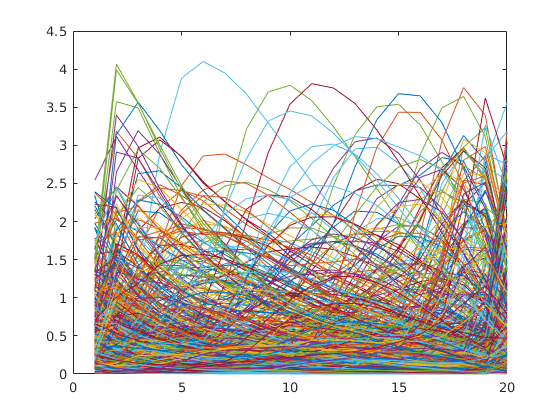

figure
plot(mus(:,1:20)')

calc_var_hwhm(mus)

ans = 6.6254

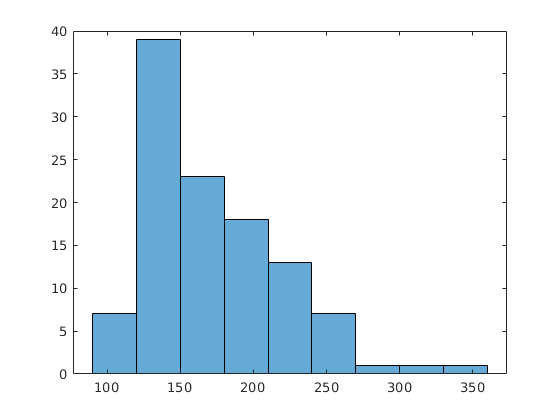

histogram(cellfun(@calc_var_hwhm, cellfun(@cell2mat, org.fetch('mus'), 'UniformOutput', false)) * 6^2)

figure;
org.correlogram('var_fwhm_cm', 'signal_var_norm', true, true, true);

Using only 73 out of 110 sessions
Mouse-aggregated correlations var_fwhm_cm vs. signal_var_norm: adj. R^2 = 0.361
Pearson: -0.657, p = 3.887133e-02, *
Spearman: -0.600, p = 7.311988e-02, n.s.
Kendall: -0.467, p = 7.255015e-02, n.s.


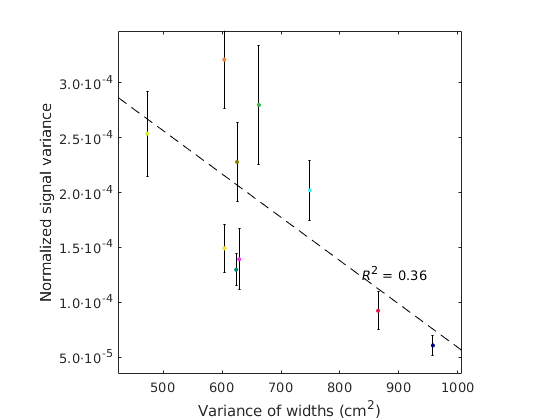

axis square;
xlabel 'Variance of widths (cm^2)'
ylabel 'Normalized signal variance'
Utils.fix_exponent(gca, 'y', 1);
Utils.printto('events_figs/f5_events', 'FWHM_vs_NSV.pdf');

function var_hwhm = calc_var_hwhm(mus)
[n_cells, n_bins] = size(mus);
assert(n_bins == 40);
[hwhm_r, hwhm_l] = deal(zeros(1, n_cells));
for i = 1:n_cells
    mu_r = mus(i, 1:20);
    mu_l = mus(i, 21:40);
    
    if all(mu_r == mu_r(1))
        hwhm_r(i) = nan;
    else
        hwhm_r(i) = one_hwhm(mu_r);
    end
    
    if all(mu_l == mu_l(1))
        hwhm_l(i) = nan;
    else
        hwhm_l(i) = one_hwhm(mu_l);
    end
end
var_hwhm = var([hwhm_r hwhm_l], 'omitnan');
end

function hwhm = one_hwhm(x)
x = x - min(x);
[mx, ix_max] = max(x);
hmx = mx/2;

pre_x = x(1:ix_max);
post_x = x(ix_max:end);

left_bound = find(pre_x < hmx, 1, "last");
if isempty(left_bound)
    left_hw = -inf;
else
    left_hw = ix_max - left_bound;
end

right_bound = find(post_x < hmx, 1, "first");
if isempty(right_bound)
    right_hw = -inf;
else
    right_hw = right_bound - 1;
end

hwhm = max(left_hw, right_hw);
if hwhm < 0
    assert(all(x >= hmx));
    warning('Value never dipped below half max.');
    hwhm = round(numel(x)/2);
end
end